## Set up

clc
clear
clf
rng(16);

### Preprocessing

FullSet = readtable("process_model\generated_data_take2\training\No_Noise\measured_data_combined.csv");
X = FullSet(:,2:3);
X.f_LO_measured = FullSet.f_LO_measured;
X.f_LE_measured = FullSet.f_LE_measured;
X.c_RaffP_measured = FullSet.c_RaffP_measured;
X.c_RaffS_measured = FullSet.c_RaffS_measured;
X.c_BO_measured = FullSet.c_BO_measured;

X_N = normalize(X);

y = FullSet.fault_state;

rng('default'); % For reproducibility
cv = cvpartition(y, 'Holdout', 0.3); % 70% training, 30% testing
X_train_LDA = X_N(training(cv), :);
y_train_LDA = y(training(cv));
X_test_LDA = X_N(test(cv), :);
y_test_LDA = y(test(cv));

### Train LDA model for kNN dimensionality reduction

% Apply LDA for dimensionality reduction on the training data
num_components = 4; % Number of components in the reduced space
lda_model_kNN = fitcdiscr(X_N, y); % Fit the LDA model
[eigenvectors_kNN, eigenvalues_kNN] = eig(lda_model_kNN.BetweenSigma, lda_model_kNN.Sigma);
[~, sorted_indices_kNN] = sort(diag(eigenvalues_kNN), 'descend');
projection_matrix_kNN = eigenvectors_kNN(:, sorted_indices_kNN(1:num_components));

% Project training and testing data onto the LDA components
X_reduced = table2array(X_N) * projection_matrix_kNN;

### Train LDA model 

lda_model = fitcdiscr(X_train_LDA, y_train_LDA); % Fit the LDA model
[eigenvectors_LDA, eigenvalues_LDA] = eig(lda_model.BetweenSigma, lda_model.Sigma);
[~, sorted_indices_LDA] = sort(diag(eigenvalues_LDA), 'descend');
projection_matrix_LDA = eigenvectors_LDA(:, sorted_indices_LDA(1:num_components));

% Project training and testing data onto the LDA components
X_train_reduced = table2array(X_train_LDA) * projection_matrix_LDA;
X_test_reduced = table2array(X_test_LDA) * projection_matrix_LDA;

lda_reduced = fitcdiscr(X_train_reduced, y_train_LDA);

### kNN CV

k_values = [1:10, linspace(20,200, 19)];
cv_accuracies = zeros(1,length(k_values));
k_fold = 10;
cv = cvpartition(length(y), 'KFold', k_fold);

for i = 1:length(k_values)
    k = k_values(i);
    accuracies = zeros(1, k_fold);
    
    for fold = 1:k_fold
        trn = training(cv, fold);
        tst = test(cv, fold);
        
        X_train = X_reduced(trn, :);
        y_train = y(trn);
        X_test = X_reduced(tst, :);
        y_test = y(tst);
        
        % Train kNN for current k
        kNN_model = fitcknn(X_train, y_train, 'NumNeighbors', k);
        
        y_pred = predict(kNN_model, X_test);
        
        accuracy = sum(y_pred == y_test) / length(y_test);
        accuracies(fold) = accuracy;
        
    end
    
    cv_accuracies(i) = mean(accuracies);
end
[M, I] = max(cv_accuracies);
best_k = k_values(I);

disp(['Best k: ', num2str(best_k)]);

Best k: 1


disp(['Cross validation accuracy with best k: ', num2str(M)]);

Cross validation accuracy with best k: 0.99514


% train final kNN model
final_kNN_model = fitcknn(X_train,y_train, 'NumNeighbors', 80);

### kNN Confusion Charts

% Predict on the test data and calculate the confusion matrix
[y_pred_kNN, scores_kNN, cost_kNN] = predict(final_kNN_model, X_test);
kNN.c = confusionmat(y_test, y_pred_kNN);
disp('kNN Confusion Matrix:');

kNN Confusion Matrix:


disp(kNN.c);

       25894           7           0           1           0
         146        8235           0           0           0
         142           0        1778           6           0
          88           0           0        6182           0
         685           0           0           0          36



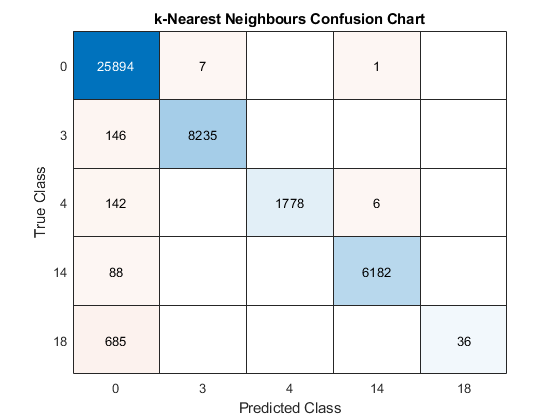


confusionchart(y_test, y_pred_kNN)
title('k-Nearest Neighbours Confusion Chart');
print('process_model/generated_data_take2/training/No_Noise/Results/kNN_2comp_confchart', '-dpng', '-r600')

mean(y_pred_kNN == y_test)

ans = 0.9751


kNN.c = confusionmat(y_test, y_pred_kNN);
kNN.c_correct = diag(kNN.c);
kNN.c_correct_sq = [zeros(4, 1) diag(kNN.c_correct(2:end))];
kNN.c_faulty = kNN.c(2:end, :);
kNN.TP = sum(kNN.c_correct_sq, "all");
kNN.false = kNN.c - diag(kNN.c_correct);
kNN.FP = sum(kNN.false(:, 2:end), "all");
kNN.FN = sum(kNN.c(2:end, 1));
kNN.TN = kNN.c(1,1);
kNN.precision = kNN.TP/(kNN.TP+kNN.FP);
kNN.sensitivity = kNN.TP/(kNN.TP+kNN.FN);
kNN.specificity = kNN.TN/(kNN.TN+kNN.FP);

Predictions

[ldaPredClass, ldaPredPosterior] = predict(final_kNN_model,X_test);
mean(ldaPredClass == y_test)

ans = 0.9751

### LDA Confusion charts

% Predict on the test data and calculate the confusion matrix
[y_pred_LDA, scores_LDA, cost_LDA] = predict(lda_reduced, X_test_reduced);
LDA.c = confusionmat(y_test_LDA, y_pred_LDA);
disp('LDA Confusion Matrix:');

LDA Confusion Matrix:


disp(LDA.c);

       77890           0          43           4           0
        7967       17084           0           0           0
        3971           0        1898           0           0
        5102           0           0       13446           0
        2196           0           0           0           0



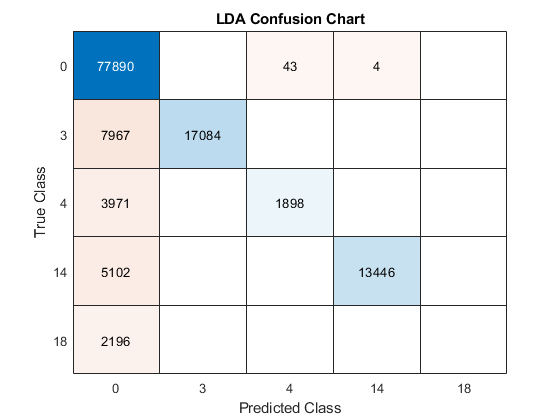


confusionchart(y_test_LDA, y_pred_LDA)
title('LDA Confusion Chart');
print('process_model/generated_data_take2/training/No_Noise/Results/LDA_2comp_confchart', '-dpng', '-r600')

mean(y_pred_LDA == y_test_LDA)

ans = 0.8512


LDA.c = confusionmat(y_test_LDA, y_pred_LDA);
LDA.c_correct = diag(LDA.c);
LDA.c_correct_sq = [zeros(4, 1) diag(LDA.c_correct(2:end))];
LDA.c_faulty = LDA.c(2:end, :);
LDA.TP = sum(LDA.c_correct_sq, "all");
LDA.false = LDA.c - diag(LDA.c_correct);
LDA.FP = sum(LDA.false(:, 2:end), "all");
LDA.FN = sum(LDA.c(2:end, 1));
LDA.TN = LDA.c(1,1);
LDA.precision = LDA.TP/(LDA.TP+LDA.FP);
LDA.sensitivity = LDA.TP/(LDA.TP+LDA.FN);
LDA.specificity = LDA.TN/(LDA.TN+LDA.FP);

LDA_accuracy = mean(y_pred_LDA == y_test_LDA);

### Save results

results = table();
results.labels = ["Precision"; "Sensitivity"; "Specificity"];
results.LDA_value = [LDA.precision; LDA.sensitivity; LDA.specificity];
results.kNN_value = [kNN.precision; kNN.sensitivity; kNN.specificity];
writetable(results, "process_model/generated_data_take2/training/No_Noise/Results/LDA_2comp_and_kNN_results.csv");


k_vals = [1; 2; 3; 10; 20; 30; 40; 50; 60; 70; 80; 90; 100];
for i = 1:length(k_vals);
    k_accuracy(i) = cv_accuracies(k_vals(i));
end
accuracy_chart = table();
accuracy_chart.k_vals = k_vals;
accuracy_chart.accuracy = k_accuracy';
accuracy_chart.LDA_2_accuracy = [LDA_accuracy; zeros((length(k_vals)-1),1)];

writetable(accuracy_chart, "process_model/generated_data_take2/training/No_Noise/Results/LDA_2comp_and_kNN_accuracies.csv");

### ROC Curves

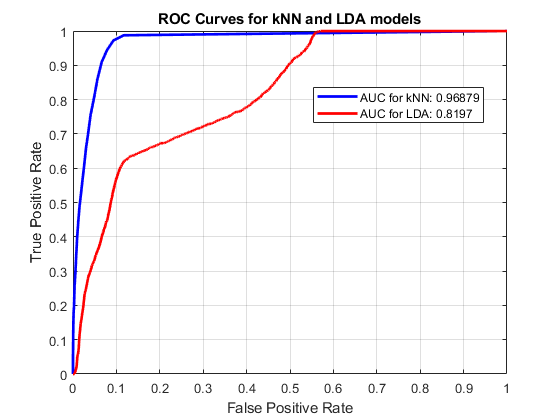

% Convert the labels to binary for ROC curve analysis (1: Positive, others: Negative)
current = 18;
labels_binary_kNN = y_test;
labels_binary_kNN(labels_binary_kNN == current) = 1;
labels_binary_kNN(labels_binary_kNN ~= 1) = 0;

% Calculate the ROC curve and AUC for kNN kernel
[X_roc_kNN, Y_roc_kNN, ~, AUC_kNN] = perfcurve(labels_binary_kNN, scores_kNN(:, 5), 1);

% Convert the labels to binary for ROC curve analysis (1: Positive, others: Negative)
labels_binary_LDA = y_test_LDA;
labels_binary_LDA(labels_binary_LDA == current) = 1;
labels_binary_LDA(labels_binary_LDA ~= 1) = 0;

% Calculate the ROC curve and AUC for LDAnomial kernel
[X_roc_LDA, Y_roc_LDA, ~, AUC_LDA] = perfcurve(labels_binary_LDA, scores_LDA(:, 5), 1);

% Plot the ROC curves for both kernels
figure;
plot(X_roc_kNN, Y_roc_kNN, 'b-', 'LineWidth', 2);
hold on;
plot(X_roc_LDA, Y_roc_LDA, 'r-', 'LineWidth', 2);
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title('ROC Curves for kNN and LDA models');
legend(['AUC for kNN: ', num2str(AUC_kNN)], ['AUC for LDA: ', num2str(AUC_LDA)], 'Location', 'Best');
grid on;
hold off;
print('process_model/generated_data_take2/training/No_Noise/Results/LDA_2comp_and_kNN_ROC_PS18', '-dpng', '-r600')